% #2

Tau = [0.18 0.42 0.61 0.81 1.01];

Del_P = [74.7 158.6 263.2 377.1 498.5];

X = linspace(-1.71,0,1e3); % for this, linspace(lowest x-axis value, highest, # of desired points)


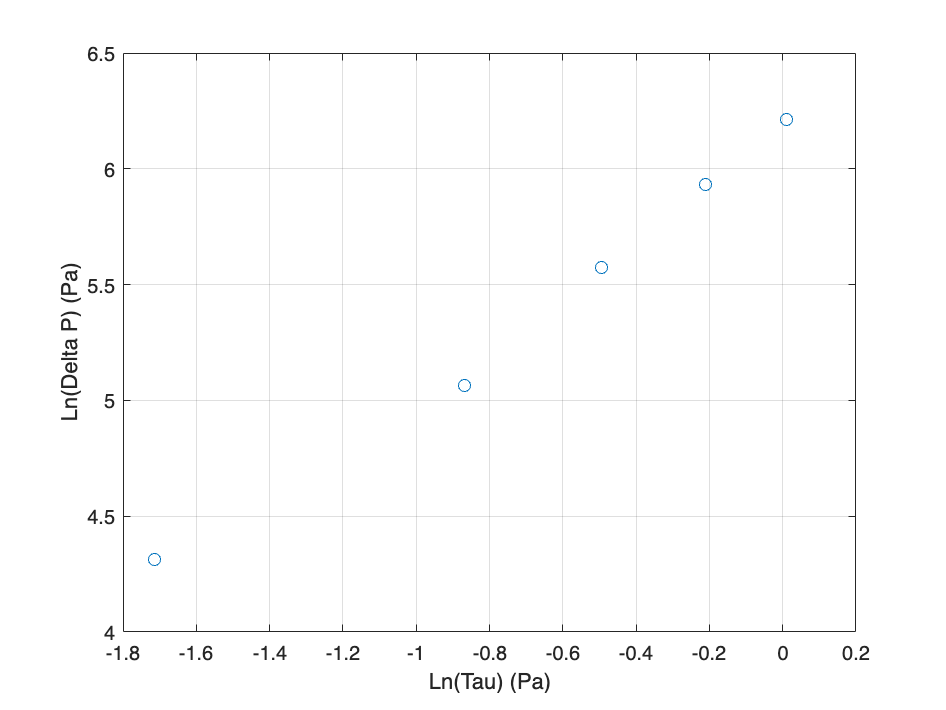

plot(log(Tau), log(Del_P),'o')
xlabel('Ln(Tau) (Pa)')
ylabel('Ln(Delta P) (Pa)')
grid on

hold on

p1 = polyfit(log(Tau), log(Del_P), 1)

p1 =     1.1051    6.1438



y_fit1 = polyval(p1, X);

y_cfit1 = polyval(p1, log(Tau));

sig_y1 = sqrt((sum((log(Del_P) - y_cfit1).^2)/(length(log(Tau))-2)));

err1 = t_value(0.9, length(log(Tau))-2)*sig_y1

err1 = 0.2042


plot(X, y_fit1, 'r-', 'DisplayName', 'Degree 1 Polynomial');

errorbar(log(Tau), log(Del_P), err1, 'k', 'LineWidth', 1)


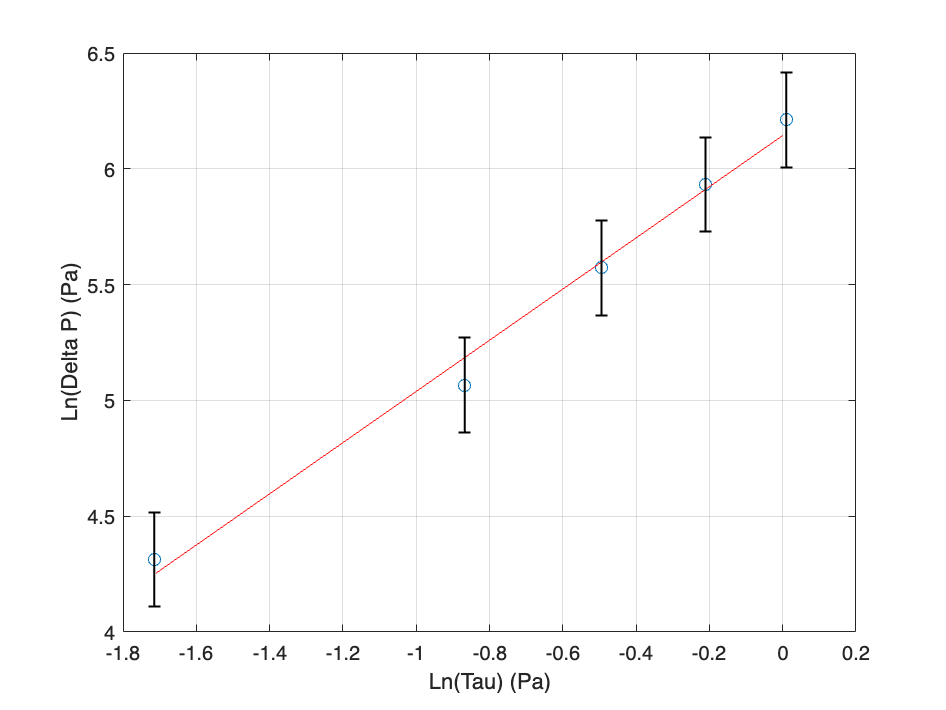

sig_y_2 = [0.05 0.05 0.05 0.05 0.05];
w = 1./(sig_y_1.^2);
x_2_2 = log(Tau).^0.5;
conf = 0.9;
nu = length(Tau) - 1;

delta = sum(w) * sum(w .* x_2) - (sum(w .* x_2_2))^2;
A_2 = (sum(w .* x_2) * sum(w .* y_2) - sum(w .* x_2_2) * sum(w .* x_2_2 .* y_2)) / delta
B_2 = (sum(w) * sum(w .* x_2_2 .* y_2) - sum(w .* x_2_2) * sum(w .* y_2)) / delta

sig_a = sqrt(sum(w .* x_2) / delta);
err_abs_a = sig_a * tinv(conf, nu)
sig_b = sqrt(sum(w) / delta);
err_abs_b = sig_b * tinv(conf, nu)
x_2_smooth = linspace(1, 10, 1000);
y_2_smooth = A_2 + B_2 * x_2_smooth.^0.5;

errorbar(x_2, y_2, sig_y_2, 'ok', 'DisplayName', 'Error Bars');
plot(x_2_smooth, y_2_smooth, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Weighted Fit');

hold off

R = 100;

C1 = 1 * 10^-6;

C2 = 100 * 10^-6;

C = C1 + C2;

ksi = 0.7

ksi = 0.7000

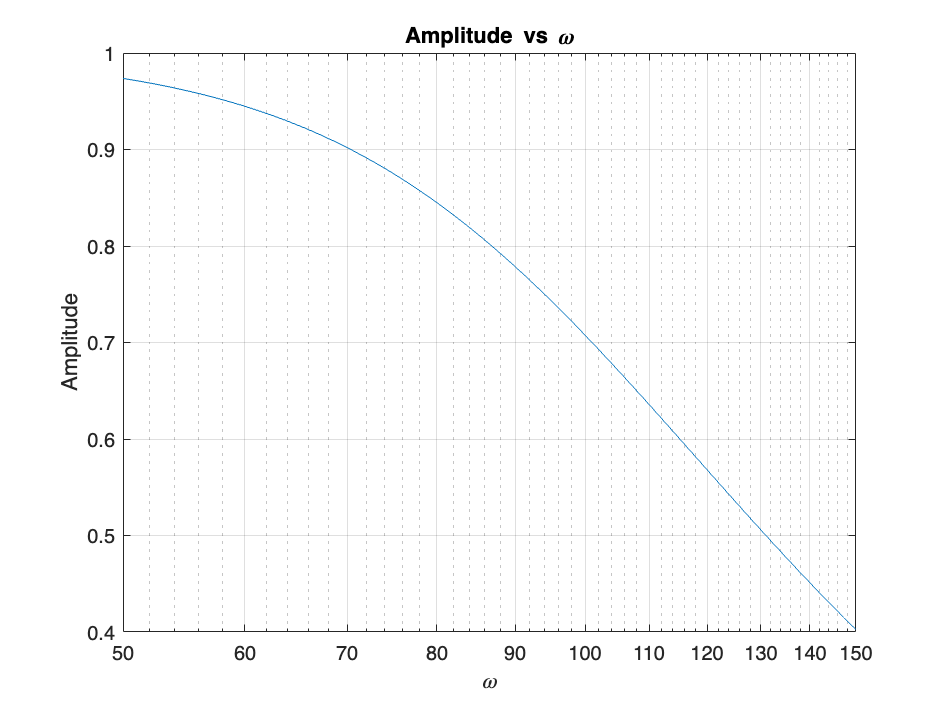


% (1 - (om*R*C)^2)^2 + (2*ksi(om*R*C))^2)


% Define the range for om (angular frequency)
om = logspace(log10(50), log10(150), 1000); % Generate 1000 logarithmically spaced values between 50 and 150


% Calculate Amp
Amp = 1 ./ sqrt((1 - (om*R*C).^2).^2 + (2*ksi*(om*R*C)).^2);

% Plot the amplitude using semilogx
semilogx(om, Amp);
xlabel('\omega');
ylabel('Amplitude');
title('Amplitude vs \omega');
grid on;